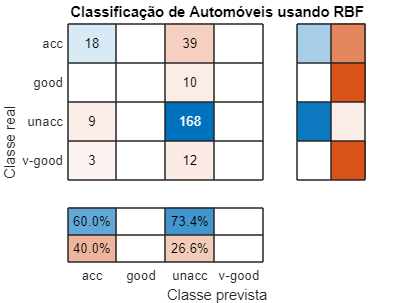

clear();
load("parametros.mat");
load("dados_val_teste.mat");
load("aberturas.mat");
load("centros.mat");
dados = dados_val_teste;

% Divisão em Validação e Teste
P = 0.50 ;
dimensoes = size(dados);
idx = randperm(dimensoes(1))  ;
validacao = dados(idx(1:round(P*dimensoes(1))),:) ; 
classe_validacao = validacao(:,end)';
validacao = validacao(:,1:end-1);
teste = dados(idx(round(P*dimensoes(1))+1:end),:);
dimensoes = size(validacao);

k = 1; H = 5;
I = dimensoes(2); n = dimensoes(1); 

MSE = 0; 

bias_oh = bias_oh;
Woh = Woh;

predicoes = [];
Xs = [];
for i = 1:n
            % Calcular a entrada da camada escondida
            X = validacao(i, :)';
            % Calcular a saida da camada escondida
            u = [];
            for idx = 1:H
                u = [u; norm(X - Chi(idx, :))^2];
            end
            Yh = [];
            for idx = 1:H
                Yh = [Yh; 1/(exp(u(idx) / (2*(sigmas(idx)^2))))];
            end
            % Calcular a entrada da camada de saida
            net_o = Woh * Yh + bias_oh* ones(1, size(Yh,2) ) ;
            % Calcular a saida rede neural
            Y = k *net_o;
            predicoes(i) = round(Y);
            Xs(i) = i;
end
figure;


% convertendo os valores da classe e das predições para valores
% categóricos.
cat_predicoes = {};
cat_classes = {};
for i = 1:length(predicoes)
   if(predicoes(i) == 4)
        cat_predicoes(i) = {'unacc'};
   elseif(predicoes(i) == 3)
        cat_predicoes(i) = {'acc'};
   elseif(predicoes(i) == 2)
       cat_predicoes(i) = {'good'};
   else
       cat_predicoes(i) = {'v-good'};
   end

   if(classe_validacao(i) == 4)
        cat_classes(i) = {'unacc'};
   elseif(classe_validacao(i) == 3)
       cat_classes(i) = {'acc'};
   elseif(classe_validacao(i) == 2)
       cat_classes(i) = {'good'};
   else
       cat_classes(i) = {'v-good'};
   end
end 
cm = confusionchart(cat_classes,cat_predicoes);
cm.Title = 'Classificação de Automóveis usando RBF';
cm.XLabel = 'Classe prevista';
cm.YLabel = 'Classe real';
cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';

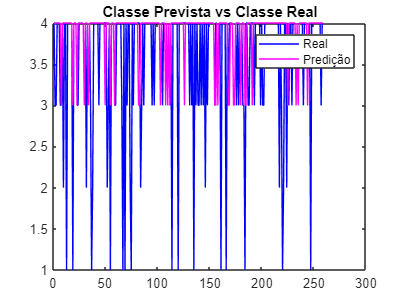

ans =      4
     4
     4
     4
     4
     4
     4
     3
     4
     4


ans =      4
     3
     3
     4
     4
     4
     3
     3
     4
     2


plot(Xs,classe_validacao,'b',Xs, predicoes,'m');
title('Classe Prevista vs Classe Real')
legend('Real', 'Predição')